clear;clc;
load('v-t.mat')
vmax=vmax(2:end);
dt=dt(2:end);
% 清理离群值、平滑化曲线

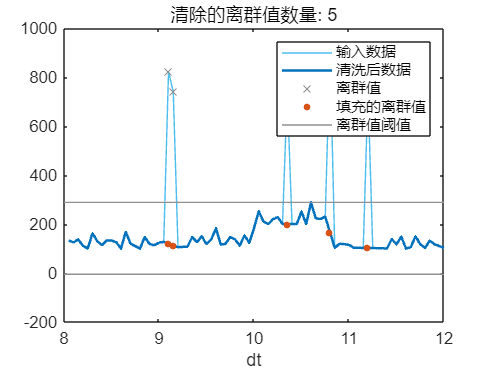

% 填充离群值
[vmax1,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(vmax, ...
    "makima","gesd","SamplePoints",dt);

% 显示结果
figure
plot(dt,vmax,"SeriesIndex",6,"DisplayName","输入数据")
hold on
plot(dt,vmax1,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","清洗后数据")

% 绘制离群值
plot(dt(outlierIndices),vmax(outlierIndices),"x","Color",[145 145 145]/255, ...
    "DisplayName","离群值")

% 绘制填充的离群值
plot(dt(outlierIndices),vmax1(outlierIndices),".","MarkerSize",12, ...
    "SeriesIndex",2,"DisplayName","填充的离群值")

% 绘制离群值阈值
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]], ...
    "Color",[145 145 145]/255,"DisplayName","离群值阈值")

hold off
title("清除的离群值数量: " + nnz(outlierIndices))
legend
xlabel("dt")

clear thresholdLow thresholdHigh

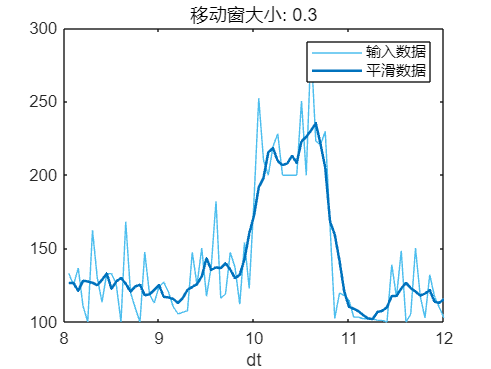

% 对输入数据进行平滑处理
[vmax2,winSize] = smoothdata(vmax1,"movmean","SmoothingFactor",0.25, ...
    "SamplePoints",dt);

% 显示结果
figure
plot(dt,vmax1,"SeriesIndex",6,"DisplayName","输入数据")
hold on
plot(dt,vmax2,"SeriesIndex",1,"LineWidth",1.5,"DisplayName","平滑数据")
hold off
title("移动窗大小: " + string(winSize));
legend
xlabel("dt")

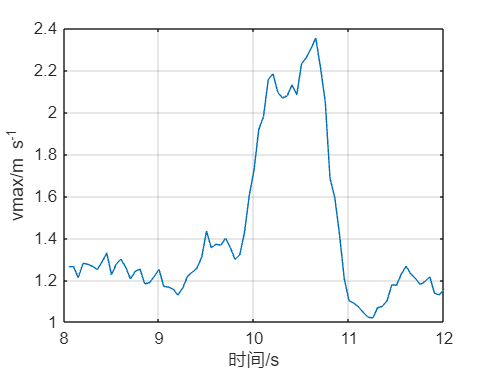

clear winSize
plot(dt,vmax2/100)
xlabel('时间/s')
ylabel('vmax/m s^{-1}')
grid on

vmax_mean=mean(vmax2);
% 由于各部分速度随着龙头的速度线性递增，所以有
vmax_Dragon=100/vmax_mean*200;
disp(['龙头的最大速度为:',num2str(vmax_Dragon),'cm/s'])

龙头的最大速度为:141.1757cm/s


% 由于数据变化较大，结果可能不准确
% PS:若采用数学方法，而非差分法，结果会更加准确